# Plot results of FWI tests

## Introduction

Plot results of tomography and FWI

**Author**: Ivan Abakumov

**Publication date**: 19.06 2019

**E-mail**: [abakumov_ivan@mail.ru](mailto:abakumov_ivan@mail.ru)

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

INV_settings;

## Result of tomography and FWI

resultfolder = [mlibfolder '/Examples/Paper_Role_of_diffractions_in_velocity_model_building/result'];
% Tomography
fname_dV = [resultfolder '/TOMO/TOMO_First_dv_111.mat'];
dV = zeros(G.nx, G.nz); 
dV(target.xx,target.zz) = MLD(fname_dV); 
velmod.tomo = bvelmod + dV;

% FWI, diving only
fname_dV = [resultfolder '/FWI_diving_only/FWI_First_dv_55.mat'];
dV = zeros(G.nx, G.nz); 
dV(target.xx,target.zz) = MLD(fname_dV); 
velmod.fwi1 = bvelmod + dV;

% FWI, diving and reflections
fname_dV = [resultfolder '/FWI_diving_ref/FWI_First_dv_59.mat'];
dV = zeros(G.nx, G.nz); 
dV(target.xx,target.zz) = MLD(fname_dV); 
velmod.fwi2 = bvelmod + dV;

% FWI, full wavefield
fname_dV = [resultfolder '/FWI_diving_ref_diff/FWI_First_dv_59.mat'];
dV = zeros(G.nx, G.nz); 
dV(target.xx,target.zz) = MLD(fname_dV); 
velmod.fwi3 = bvelmod + dV;

figure(1)
fig = figure('Position', [900 400 570 750])

fig =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [900 400 570 750]
       Units: 'pixels'

  Show all properties


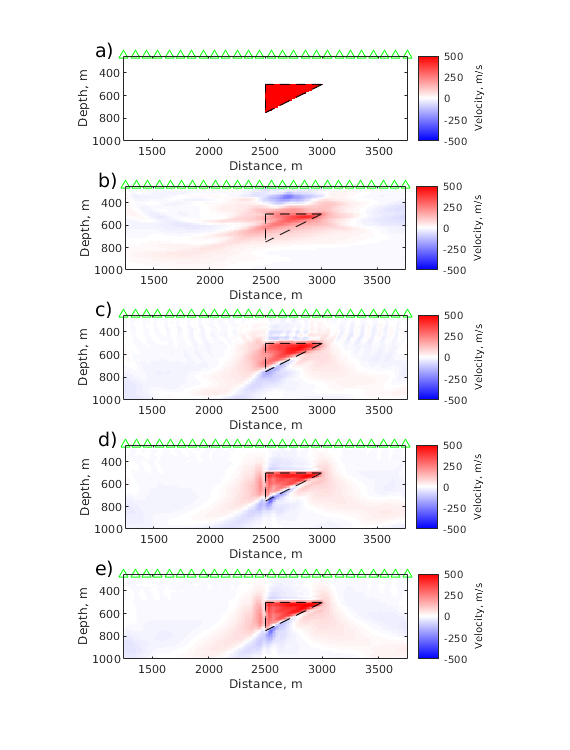

subplot(5,1,1)
imagesc(G.xx, G.zz,  mvelmod'-bvelmod')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
%title('True velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
text(1000,200,'a)','FontSize',14);


subplot(5,1,2)
imagesc(G.xx, G.zz, SME(velmod.tomo'-bvelmod',1))
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
%title('Reconstructed velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
text(1000,200,'b)','FontSize',14);

subplot(5,1,3)
imagesc(G.xx, G.zz, SME(velmod.fwi1-bvelmod,1)')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
%title('Reconstructed velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
text(1000,200,'c)','FontSize',14);

subplot(5,1,4)
imagesc(G.xx, G.zz, SME(velmod.fwi2-bvelmod,1)')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
%title('Reconstructed velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
text(1000,200,'d)','FontSize',14);

subplot(5,1,5)
imagesc(G.xx, G.zz, SME(velmod.fwi3-bvelmod,1)')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
%title('Reconstructed velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
text(1000,200,'e)','FontSize',14);

figure(1)
fig = figure('Position', [100 100 570 150])

fig =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 570 150]
       Units: 'pixels'

  Show all properties


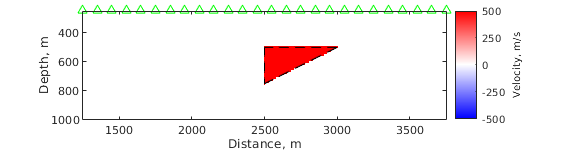

imagesc(G.xx, G.zz,  mvelmod'-bvelmod')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
%title('True velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

%text(1000,200,'a)','FontSize',14);


figure(2)
fig = figure('Position', [100 100 570 150])

fig =   Figure (9) with properties:

      Number: 9
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 570 150]
       Units: 'pixels'

  Show all properties


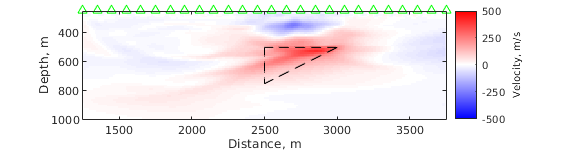

imagesc(G.xx, G.zz, SME(velmod.tomo'-bvelmod',1))
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
%title('Reconstructed velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

%text(1000,200,'b)','FontSize',14);

figure(3)
fig = figure('Position', [100 100 570 150])

fig =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 570 150]
       Units: 'pixels'

  Show all properties


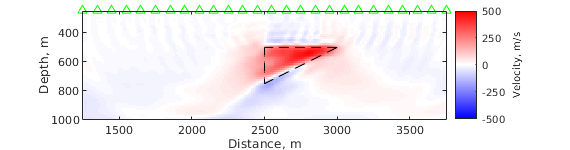

imagesc(G.xx, G.zz, SME(velmod.fwi1-bvelmod,1)')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
%title('Reconstructed velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

%text(1000,200,'c)','FontSize',14);

figure(4)
fig = figure('Position', [100 100 570 150])

fig =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 570 150]
       Units: 'pixels'

  Show all properties


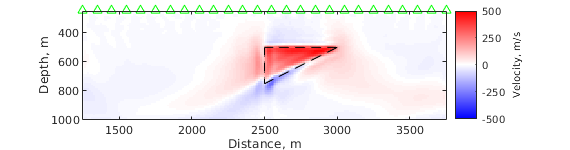

imagesc(G.xx, G.zz, SME(velmod.fwi2-bvelmod,1)')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
%title('Reconstructed velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

%text(1000,200,'d)','FontSize',14);

figure(5)
fig = figure('Position', [100 100 570 150])

fig =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 570 150]
       Units: 'pixels'

  Show all properties


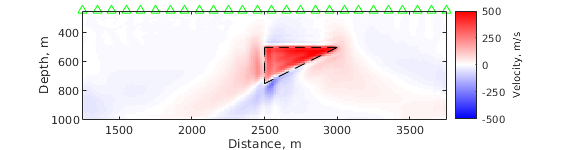

imagesc(G.xx, G.zz, SME(velmod.fwi3-bvelmod,1)')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
%title('Reconstructed velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

%text(1000,200,'e)','FontSize',14);

figure(21)
fig = figure('Position', [100 100 570 150])

fig =   Figure (13) with properties:

      Number: 13
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 570 150]
       Units: 'pixels'

  Show all properties


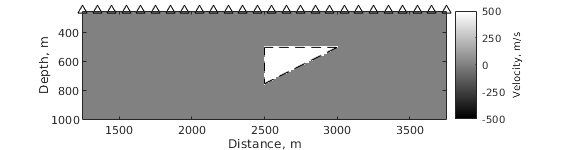

imagesc(G.xx, G.zz,  mvelmod'-bvelmod')
hold on
plot(acq.sx, acq.sz, 'k^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
colormap('gray');




figure(22)
fig = figure('Position', [100 100 570 150])

fig =   Figure (14) with properties:

      Number: 14
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 570 150]
       Units: 'pixels'

  Show all properties


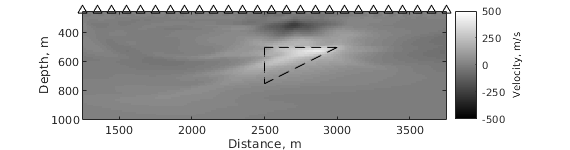

imagesc(G.xx, G.zz, SME(velmod.tomo'-bvelmod',1))
hold on
plot(acq.sx, acq.sz, 'k^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
colormap('gray');



figure(23)
fig = figure('Position', [100 100 570 150])

fig =   Figure (15) with properties:

      Number: 15
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 570 150]
       Units: 'pixels'

  Show all properties


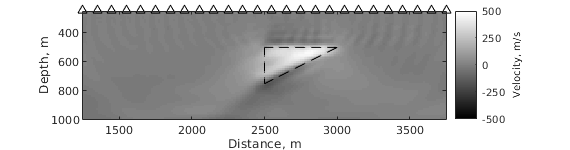

imagesc(G.xx, G.zz, SME(velmod.fwi1-bvelmod,1)')
hold on
plot(acq.sx, acq.sz, 'k^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
colormap('gray');



figure(24)
fig = figure('Position', [100 100 570 150])

fig =   Figure (16) with properties:

      Number: 16
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 570 150]
       Units: 'pixels'

  Show all properties


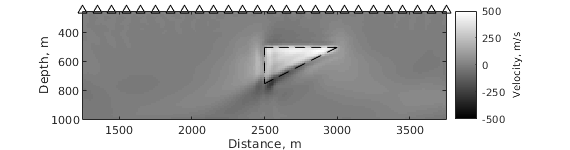

imagesc(G.xx, G.zz, SME(velmod.fwi2-bvelmod,1)')
hold on
plot(acq.sx, acq.sz, 'k^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
colormap('gray');


figure(25)
fig = figure('Position', [100 100 570 150])

fig =   Figure (17) with properties:

      Number: 17
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 570 150]
       Units: 'pixels'

  Show all properties


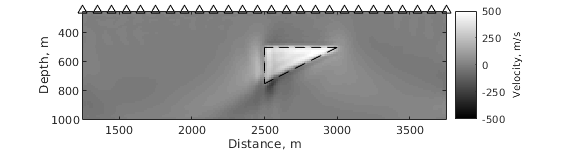

imagesc(G.xx, G.zz, SME(velmod.fwi3-bvelmod,1)')
hold on
plot(acq.sx, acq.sz, 'k^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
colormap('gray');